clearvars; clc;

# Esercitazione 2

#### Definizioni

s=tf('s');
Gcont=160/(s^2+36*s+400);

Definisco il sistema discretizzato

Ts=0.01;
G=zpk(c2d(Gcont,Ts,'zoh'))


G =
 
   0.0070974 (z+0.8869)
  -----------------------
  (z^2 - 1.664z + 0.6977)
 
Sample time: 0.01 seconds
Discrete-time zero/pole/gain model.
Model Properties


### Studio requisiti

[z_G, p_G, k_G]=zpkdata(G,'v');
B=k_G*[1 -z_G]; %numeratore di G scritto come matrice polinomiale
A=conv([1 -p_G(1)],[1 -p_G(2)]);

G1=evalfr(G,1)

G1 = 0.4000

- Kc >= 0.25

- Already satisfied because system must be type 0 but it's already type 1

s_hat=0.19;
t_s1=1;
zeta=abs(log(s_hat))/(sqrt(pi^2+(log(s_hat))^2))

zeta = 0.4673

wn=4.6/(zeta*t_s1)

wn = 9.8428

#### Damping area

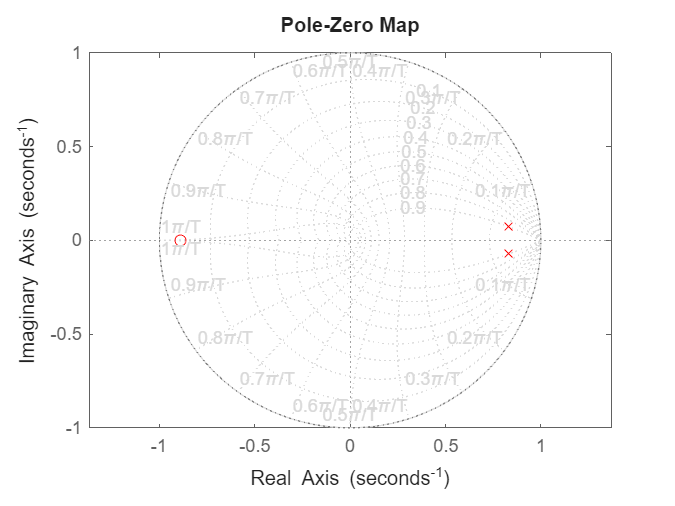

pzmap(G,'r');
axis('equal');
hold on
zgrid(zeta,0,Ts)